我们现在使用实时脚本来进行编程，实时脚本可以看成一个笔记本，能很方便的显示代码和对应的运行结果。

clc;clear

先把当前文件夹修改成数据所在的这个文件夹。

% cd 'C:\Users\sxjmqf\Desktop\机器学习进阶课程\1.鸢尾花数据集'

导入 鸢尾花种类已知 的那个数据，我们可以偷懒，使用导入数据工具箱（下面是自动生成的代码）

可以在里面修改数据的变量名和每一列指标的名称

%% 导入数据
[~, ~, raw] = xlsread('鸢尾花1.xlsx','Sheet1','A2:E145');
stringVectors = string(raw(:,5));
stringVectors(ismissing(stringVectors)) = '';
raw = raw(:,[1,2,3,4]);

%% 创建输出变量
data = reshape([raw{:}],size(raw));

%% 创建表
data1 = table;

%% 将导入的数组分配给列变量名称
data1.VarName1 = data(:,1);
data1.VarName2 = data(:,2);
data1.VarName3 = data(:,3);
data1.VarName4 = data(:,4);
data1.VarName5 = categorical(stringVectors(:,1));

%% 清除临时变量
clearvars data raw stringVectors;


实时编辑器中按快捷键 Ctrl+Enter 可以运行当前节的代码

data1

data1 = 144×5 table
    VarName1    VarName2    VarName3    VarName4     VarName5 
    ________    ________    ________    ________    __________

        5         3.3         1.4         0.2       山鸢尾     
      6.7         3.1         4.4         1.4       变色鸢尾   
      6.3         2.7         4.9         1.8       维吉尼亚鸢尾
      4.4         2.9         1.4         0.2       山鸢尾     
      7.7         2.6         6.9         2.3       维吉尼亚鸢尾
        5         3.5         1.3         0.3       山鸢尾     
      5.7           3         4.2         1.2       变色鸢尾   
      5.9           3         5.1         1.8       维吉尼亚鸢尾
      5.5         2.4         3.8         1.1       变色鸢尾   
      5.8         2.7         3.9         1.2       变色鸢尾   
        5         3.2         1.2         0.2       山鸢尾     
      6.6           3         4.4         1.4       变色鸢尾   
      6.9         3.1         5.4         2.1       维吉尼亚鸢尾
      5.6           3         4.1         1.3       变色鸢尾   
      5.1    

实时编辑器中按快捷键 Ctrl+E 可以切换代码和文本模式

data1是table类型的数据，和我们以前的模型中用到的矩阵类型不同。

[https://ww2.mathworks.cn/help/matlab/tables.html](https://ww2.mathworks.cn/help/matlab/tables.html)

data1的最后一列就是我们的输出变量，我们可以提前在excel中调整好。

实时编辑器中按快捷键 Ctrl+Alt+Enter可以插入新的一节

下面我们导入鸢尾花种类未知的数据，同样使用导入数据工具箱

%% 导入数据
[~, ~, raw] = xlsread('鸢尾花2.xlsx','Sheet1','A2:D7');
%% 创建输出变量
data = reshape([raw{:}],size(raw));
%% 创建表
data2 = table;
%% 将导入的数组分配给列变量名称
data2.VarName1 = data(:,1);
data2.VarName2 = data(:,2);
data2.VarName3 = data(:,3);
data2.VarName4 = data(:,4);
%% 清除临时变量
clearvars data raw;

导入完数据后，就可以使用分类学习器了，可以在上方的App中点击分类学习器，也可以使用下面的代码调用。

classificationLearner
% 调用回归学习器的命令是regressionLearner

现在大家可以输入数据，选择合适的模型进行训练，然后查看结果。

如果只是简单的用现有的模型进行后续预测的话，我们点击导出模型就可以了；

%  trainedModel.predictFcn(data2)  % 导出模型后进行预测

如果需要进阶的修改，例如调参，我们需要点生成函数。（后面会大量用到这个）

我们以决策树模型为例，对于决策树模型，我们可以使用下面的代码将它可视化：

如果使用的导出模型：

% figure(1)
% view(trainedModel.ClassificationTree,'Mode','graph')  % 根据你自己导出来的模型名称修改

如果是生成函数：需要加上这一句 view(trainedClassifier.ClassificationTree,'Mode','graph')

需要去掉MATLAB导出的这个函数的第一行，并在最前面重新加入一行语句，来指定训练的数据。

rng(521)  % 设置随机数种子，保证运行的结果一样
trainingData = data1;
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
predictors = inputTable(:, predictorNames);  % 输入
response = inputTable.VarName5;  % 输出
isCategoricalPredictor = [false, false, false, false];

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
classificationTree = fitctree(...
    predictors, ...
    response, ...
    'SplitCriterion', 'gdi', ...
    'MaxNumSplits', 4, ...
    'Surrogate', 'off', ...
    'ClassNames', categorical({'变色鸢尾'; '山鸢尾'; '维吉尼亚鸢尾'}));

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
treePredictFcn = @(x) predict(classificationTree, x);
trainedClassifier.predictFcn = @(x) treePredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifier.RequiredVariables = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
trainedClassifier.ClassificationTree = classificationTree;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2017a.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
predictors = inputTable(:, predictorNames);
response = inputTable.VarName5;
isCategoricalPredictor = [false, false, false, false];

% Perform cross-validation
partitionedModel = crossval(trainedClassifier.ClassificationTree, 'KFold', 5);

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
validationAccuracy

validationAccuracy = 0.9375

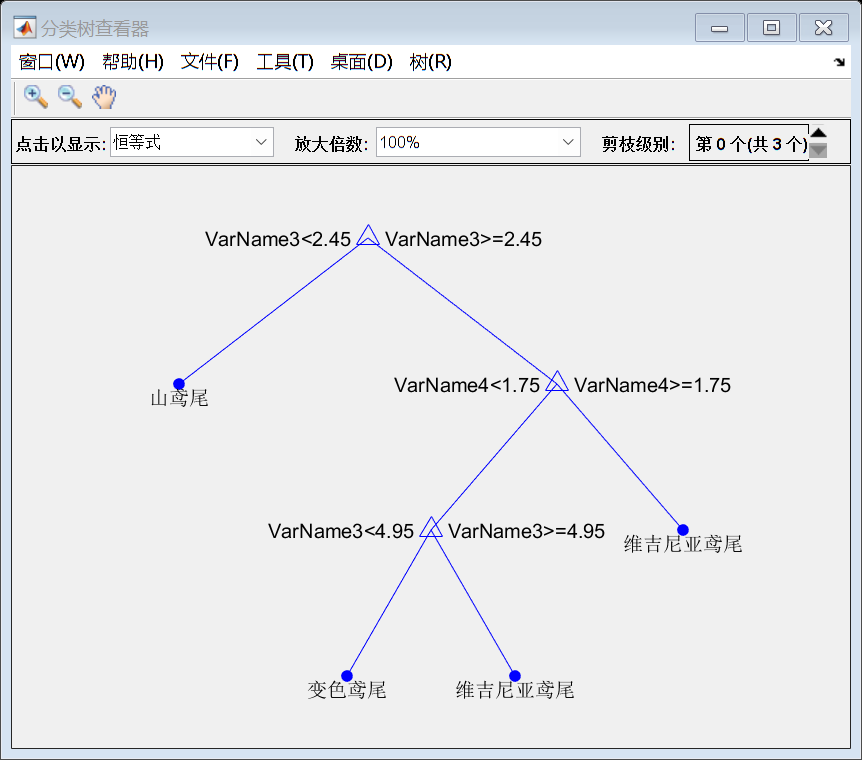

figure(2)
view(trainedClassifier.ClassificationTree,'Mode','graph')

生成函数进行预测

trainedClassifier.predictFcn(data2)

ans = 6×1 categorical 数组
     山鸢尾 
     维吉尼亚鸢尾 
     山鸢尾 
     变色鸢尾 
     维吉尼亚鸢尾 
     山鸢尾 


# 计算F1分数

目前，MATLAB中没有直接计算F1分数的内置函数，这里我们可以使用别人写的代码。

参考格式如下：

*Eugenio Bertolini (2021). Precision, Specificity, Sensitivity, Accuracy & F1-score (https://www.mathworks.com/matlabcentral/fileexchange/86158-precision-specificity-sensitivity-accuracy-f1-score), MATLAB Central File Exchange. Retrieved August 5, 2021.*

注意，原作者提交的这个代码中有一点问题，我给大家的m文件是正确的。

***函数名：statsOfMeasure.m   *****使用前需要将这个函数放到MATLAB当前文件夹下。**

**先来介绍这个Excel里面的例子**

zs = {'A','A','A','A','B','B','B','C','C'}; % 真实的结果
yc = {'A','A','B','C','B','B','C','B','C'}; % 预测的结果
ClassNames = {'A','B','C'}; % 样本有几类
C = confusionmat(zs,yc,'Order',ClassNames) % 先计算混淆矩阵（order后面指定类的顺序）

C =      2     1     1
     0     2     1
     0     1     1


stats = statsOfMeasure(C)  % 调用我们下载的那个第三方的函数（函数要放到当前文件夹）

stats = 9×4 table
          name                     classes               macroAVG    microAVG
    ________________    _____________________________    ________    ________

    "true_positive"           2          2          1     1.6667      1.6667 
    "false_positive"          0          2          2     1.3333      1.3333 
    "false_negative"          2          1          1     1.3333      1.3333 
    "true_negative"           5          4          5     4.6667      4.6667 
    "precision"               1        0.5    0.33333    0.61111     0.55556 
    "sensitivity"           0.5    0.66667        0.5    0.55556     0.55556 
    "specificity"             1    0.66667    0.71429    0.79365     0.77778 
    "accuracy"          0.55556    0.55556    0.55556    0.55556     0.55556 
    "F-measure"         0.66667    0.57143        0.4    0.54603     0.55556 


% confusionchart(zs,yc)  % 混淆矩阵的可视化 R2018b版本才被引入

最左侧的name列从上到下分别是：

         TP  FP  FN  TN  查准率或精确率  `查全率或召回率`  `特异性`  `分类准确率`  F1`分数`

`最后两列分别是Macro F1和Micro F1，我们只用管它们最下面的那个元素，上面的元素可以忽略。`

`Macro F1 = 0.54603  ;   Micro F1 = 0.55556`

`因为我们是三分类问题，所以classes下面有三列，分别表示当正类为ClassNames中的某个元素时，其对应的衡量指标。`

## `下面我们再以决策树分类鸢尾花为例，再来介绍下这个函数的使用方法：`

trainingData = data1;
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
predictors = inputTable(:, predictorNames);  % 输入
response = inputTable.VarName5;  % 输出
isCategoricalPredictor = [false, false, false, false];

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
classificationTree = fitctree(...
    predictors, ...
    response, ...
    'SplitCriterion', 'gdi', ...
    'MaxNumSplits', 4, ...
    'Surrogate', 'off', ...
    'ClassNames', categorical({'变色鸢尾'; '山鸢尾'; '维吉尼亚鸢尾'}));

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
treePredictFcn = @(x) predict(classificationTree, x);
trainedClassifier.predictFcn = @(x) treePredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifier.RequiredVariables = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
trainedClassifier.ClassificationTree = classificationTree;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2017a.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
predictors = inputTable(:, predictorNames);
response = inputTable.VarName5;
isCategoricalPredictor = [false, false, false, false];

% Perform cross-validation
partitionedModel = crossval(trainedClassifier.ClassificationTree, 'KFold', 5);

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');

下面就是利用交叉验证预测的结果和真实的结果来计算F1分数

ClassNames = unique(response) % y中各类的名称

ClassNames = 3×1 categorical 数组
     变色鸢尾 
     山鸢尾 
     维吉尼亚鸢尾 


group = response;  % y所在的那一列（真实的类别）
C = confusionmat(group,validationPredictions,'Order',ClassNames); % 先计算混淆矩阵
stats = statsOfMeasure(C)  % 调用我们下载的那个第三方的函数

stats = 9×4 table
          name                     classes               macroAVG    microAVG
    ________________    _____________________________    ________    ________

    "true_positive"          45         47         46         46          46 
    "false_positive"          2          0          4          2           2 
    "false_negative"          4          0          2          2           2 
    "true_negative"          93         97         92         94          94 
    "precision"         0.95745          1       0.92    0.95915     0.95833 
    "sensitivity"       0.91837          1    0.95833     0.9589     0.95833 
    "specificity"       0.97895          1    0.95833    0.97909     0.97917 
    "accuracy"          0.95833    0.95833    0.95833    0.95833     0.95833 
    "F-measure"          0.9375          1    0.93878    0.95876     0.95833 


使用场景：micro F1分数在计算公式中考虑到了每个类别的数量，所以适用于数据分布不平衡（各个类别的数量差异较大）的情况；macro F1分数没有考虑到数据的数量，所以会平等的看待每一类。因此，如果你的数据分布不平衡，推荐使用micro F1分数；否则两个都可以汇报，这个并不绝对。另外，如果数据极度不平衡，例如某些类只有几个样本点，这时候两种方法都不好，你可以单独汇报你关心的正类的F1分数。

tabulate(response)  % 查看每一类的样本量

   Value    Count   Percent
    变色鸢尾       49     34.03%
     山鸢尾       47     32.64%
  维吉尼亚鸢尾       48     33.33%


在我们这个题里面，样本分布均匀，micro F1和macro F1分数都可以用，你可以都汇报，也可以选择任意一个汇报。别求平均就行，没见人把它们求平均。

Macro_f1_score = stats.macroAVG(end) % macro:宏观

Macro_f1_score = 0.9588

Micro_f1_score = stats.microAVG(end) % micro:微观

Micro_f1_score = 0.9583

如果你关心某一类的F1分数，可以使用下面的代码得到它对应的F1分数

ClassNames

ClassNames = 3×1 categorical 数组
     变色鸢尾 
     山鸢尾 
     维吉尼亚鸢尾 


kk = 1;   % 指定正类，kk是正类在ClassNames中的位置
F1_score1 = stats.classes(end,kk)  % 单独指定某个正类对应的F1分数

F1_score1 = 0.9375

**注意：如果你自己的数据是二分类问题，也可以调用这个函数来计算F1分数。但是在二分类别用micro F1和macroF1分数，没见过有人在二分类用过它们）**

# ROC曲线和AUC

**ROC****曲线和****AUC****在二分类问题和多分类问题中都适用，但我们需要选好正类是哪一个，不同的正类对应的****ROC****曲线和****AUC****不同。**

ClassNames = unique(response) % y中各类的名称

ClassNames = 3×1 categorical 数组
     变色鸢尾 
     山鸢尾 
     维吉尼亚鸢尾 


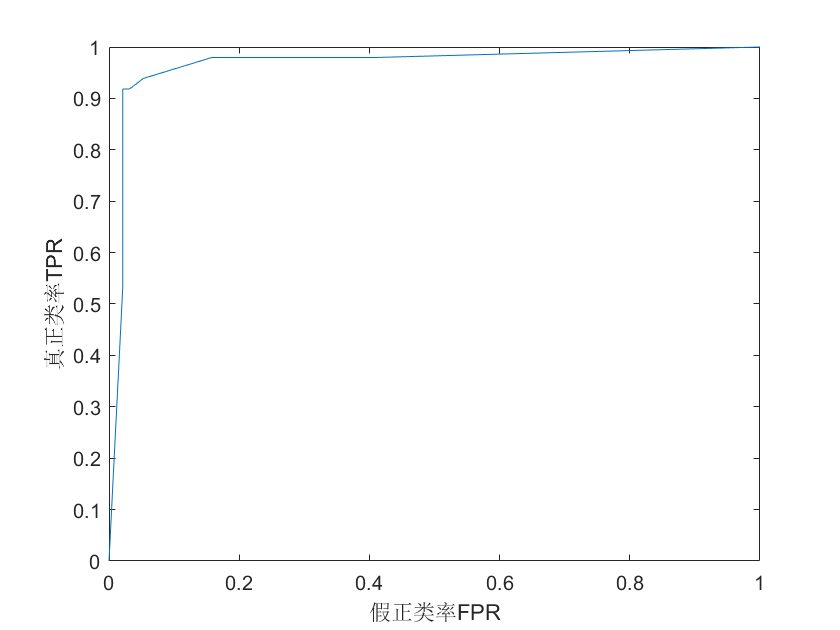

kk = 1;   % 指定正类，kk是正类在ClassNames中的位置
posclass = ClassNames(kk); % 正类的名称
group = response;  % y所在的那一列（真实的类别）
% validationScores是我们运行上面导出的代码得到的预测的分数（这个分数在不同的模型中代表的含义不同）
[x_roc,y_roc,~,auc] = perfcurve(group,validationScores(:,kk),posclass); % 第三个输出参数我们不需要，所以这里写成~
% ~是连接号的波浪线符号,在Tab键的上面  清风老师语文没学好，视频说的破折号是这个长横线——

figure(3)
plot(x_roc,y_roc)
xlabel('假正类率FPR'); ylabel('真正类率TPR');

auc

auc = 0.9667

**比较不同的模型，将ROC曲线绘制到同一个图上**

%% 决策树
rng(999)
trainingData = data1;
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
predictors = inputTable(:, predictorNames);
response = inputTable.VarName5;
isCategoricalPredictor = [false, false, false, false];

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
classificationTree = fitctree(...
    predictors, ...
    response, ...
    'SplitCriterion', 'gdi', ...
    'MaxNumSplits', 20, ...
    'Surrogate', 'off', ...
    'ClassNames', categorical({'变色鸢尾'; '山鸢尾'; '维吉尼亚鸢尾'}));

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
treePredictFcn = @(x) predict(classificationTree, x);
trainedClassifier.predictFcn = @(x) treePredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifier.RequiredVariables = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
trainedClassifier.ClassificationTree = classificationTree;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2017a.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
predictors = inputTable(:, predictorNames);
response = inputTable.VarName5;
isCategoricalPredictor = [false, false, false, false];

% Perform cross-validation
partitionedModel = crossval(trainedClassifier.ClassificationTree, 'KFold', 5);

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');

ClassNames = unique(response) % y中各类的名称

ClassNames = 3×1 categorical 数组
     变色鸢尾 
     山鸢尾 
     维吉尼亚鸢尾 


kk = 1;   % 指定正类，kk是正类在ClassNames中的位置
posclass = ClassNames(kk); % 正类的名称
group = response;  % y所在的那一列（真实的类别）
% validationScores是我们运行上面导出的代码得到的预测的分数（这个分数在不同的模型中代表的含义不同）
[x1,y1,~,auc1] = perfcurve(group,validationScores(:,kk),posclass); % 第三个输出参数我们不需要，所以这里写成~

%% SVM
rng(999)
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
predictors = inputTable(:, predictorNames);
response = inputTable.VarName5;
isCategoricalPredictor = [false, false, false, false];

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
template = templateSVM(...
    'KernelFunction', 'gaussian', ...
    'PolynomialOrder', [], ...
    'KernelScale', 0.5, ...
    'BoxConstraint', 1, ...
    'Standardize', true);
classificationSVM = fitcecoc(...
    predictors, ...
    response, ...
    'Learners', template, ...
    'Coding', 'onevsone', ...
    'ClassNames', categorical({'变色鸢尾'; '山鸢尾'; '维吉尼亚鸢尾'}));

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
svmPredictFcn = @(x) predict(classificationSVM, x);
trainedClassifier.predictFcn = @(x) svmPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifier.RequiredVariables = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
trainedClassifier.ClassificationSVM = classificationSVM;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2017a.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
predictors = inputTable(:, predictorNames);
response = inputTable.VarName5;
isCategoricalPredictor = [false, false, false, false];

% Perform cross-validation
partitionedModel = crossval(trainedClassifier.ClassificationSVM, 'KFold', 5);

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');

[x2,y2,~,auc2] = perfcurve(group,validationScores(:,kk),posclass); % 第三个输出参数我们不需要，所以这里写成~


## 最后的画图

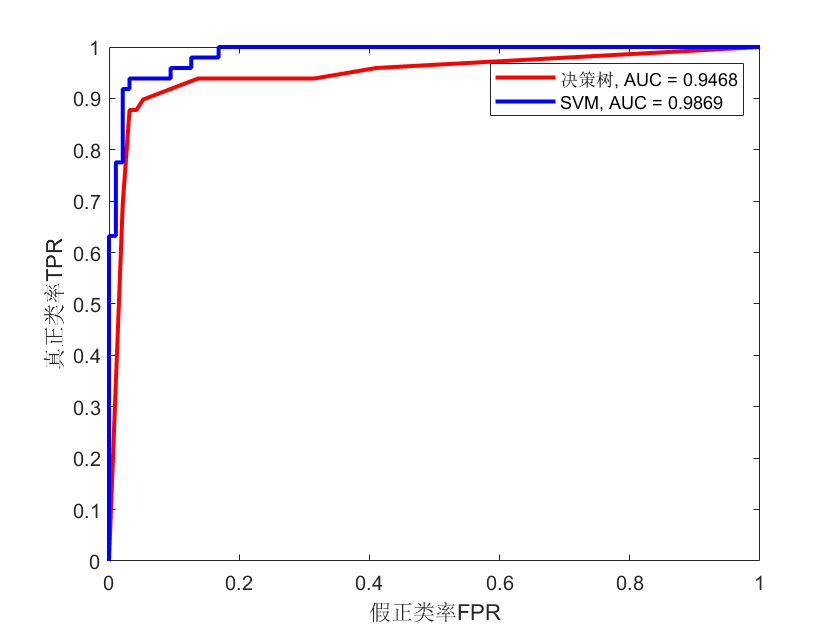

figure(4)
plot(x1,y1,'r','linewidth',2)  % 红色、线宽为2
hold on  % 继续在当前图上绘图
plot(x2,y2,'b','linewidth',2)   % 蓝色、线宽为2
xlabel('假正类率FPR'); 
ylabel('真正类率TPR');
text1 = ['决策树, AUC = ', num2str(round(auc1,4))];
text2 = ['SVM, AUC = ', num2str(round(auc2,4))];
% strcat('决策树, AUC = ', num2str(round(auc1,4))) % 老版本请用这种方法拼接字符
% "决策树, AUC = " + round(auc1,4); % MATLAB2017a版本才支持双引号的字符串
legend(text1,text2) % 加上图例

**使用网格搜索对决策树进行调参**

因为对鸢尾花进行分类是一个多分类问题，且不存在样本不平衡问题，因此我们可以考虑使用micro F1分数和macro F1分数。我这里就以micro F1分数为标准。

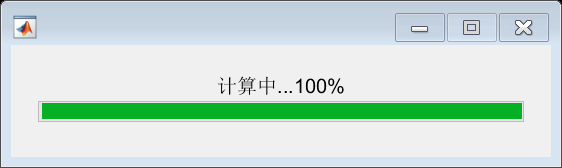

trainingData = data1;
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
predictors = inputTable(:, predictorNames);
response = inputTable.VarName5;
isCategoricalPredictor = [false, false, false, false];


% 下面这两个变量在计算F1分数时会用到
ClassNames = unique(response); % y中各类的名称
group = response;  % y所在的那一列（真实的类别）


% Train a classifier
% This code specifies all the classifier options and trains the classifier.

SplitCriterion = {'gdi','twoing','deviance'}; %分裂准则有三个可以选的，这里用元胞数组保存
MaxNumSplits = 1:30;  % 最大分裂数（因为这个问题比较简单，我这里搜索设置的最大分裂数的上界是30）
num_i = length(SplitCriterion);  % 第一个超参数SplitCriterion的可能性有3种
num_j = length(MaxNumSplits);  % 第二个超参数MaxNumSplits的可能性有30种
MICRO_F1_SCORE = zeros(num_i,num_j); % 初始化最后得到的结果（初始化是为了加快代码运行速度）
mywaitbar = waitbar(0);   % 设置一个进度条
TOTAL_NUM = num_i*num_j;  % 总共要计算多少次
now_num = 0; % 已经计算了多少次
for i = 1:num_i
    for j = 1:num_j
        rng(520)  % 设定随机数种子，保证结果的可重复性(这里的520也可以换成其他的数字)
        %   注意，如果超参数是字符类型的话，它是被保存在元胞数组中的，取出时需要使用大括号才能得到字符型
        classificationTree = fitctree(...
            predictors, ...
            response, ...
            'SplitCriterion', SplitCriterion{i}, ...
            'MaxNumSplits', MaxNumSplits(j), ...
            'Surrogate', 'off', ...
            'ClassNames', categorical({'变色鸢尾'; '山鸢尾'; '维吉尼亚鸢尾'}));
        
        %       'SplitCriterion' - Criterion for choosing a split. One of 'gdi'
        %                        (Gini's diversity index), 'twoing' for the twoing
        %                        rule, or 'deviance' for maximum deviance reduction
        %                        (also known as cross-entropy). Default: 'gdi'
        
        %       'MaxNumSplits' - Maximal number of decision splits (or branch
        %                        nodes) per tree. Default: size(X,1)-1
        
        % Create the result struct with predict function
        predictorExtractionFcn = @(t) t(:, predictorNames);
        treePredictFcn = @(x) predict(classificationTree, x);
        trainedClassifier.predictFcn = @(x) treePredictFcn(predictorExtractionFcn(x));
        
        % Add additional fields to the result struct
        trainedClassifier.RequiredVariables = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
        trainedClassifier.ClassificationTree = classificationTree;
        trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2017a.';
        trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');
        
        % Extract predictors and response
        % This code processes the data into the right shape for training the
        % model.
        inputTable = trainingData;
        predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
        predictors = inputTable(:, predictorNames);
        response = inputTable.VarName5;
        isCategoricalPredictor = [false, false, false, false];
        
        % Perform cross-validation
        partitionedModel = crossval(trainedClassifier.ClassificationTree, 'KFold', 5);
        
        % Compute validation predictions
        [validationPredictions, validationScores] = kfoldPredict(partitionedModel);
        
        % Compute validation accuracy
        validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
        
        % 下面就是计算每一次循环得到的micro F1分数
        C = confusionmat(group,validationPredictions,'Order',ClassNames);
        stats = statsOfMeasure(C);
        MICRO_F1_SCORE(i,j) = stats.microAVG(end);
        
        % 更新进度条
        now_num = now_num+1;
        mystr=['计算中...',num2str(100*now_num/TOTAL_NUM),'%'];
        waitbar(now_num/TOTAL_NUM,mywaitbar,mystr);
        
    end
end

MICRO_F1_SCORE

MICRO_F1_SCORE =     0.6667    0.9097    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236    0.9236
    0.6667    0.9097    0.9236    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375
    0.6667    0.9097    0.9236    0.9236    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306    0.9306


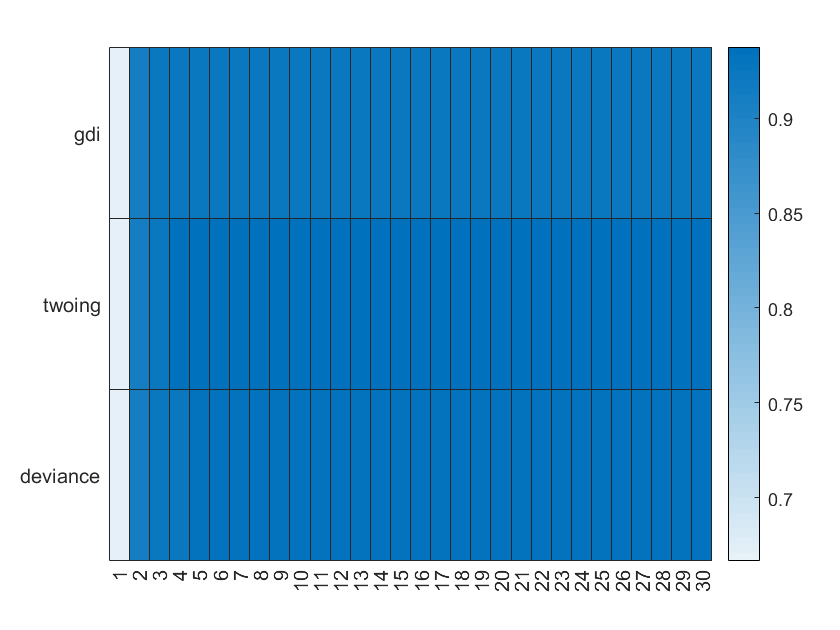

figure(5)  % 画一个热力图
heatmap(MaxNumSplits,SplitCriterion,MICRO_F1_SCORE)

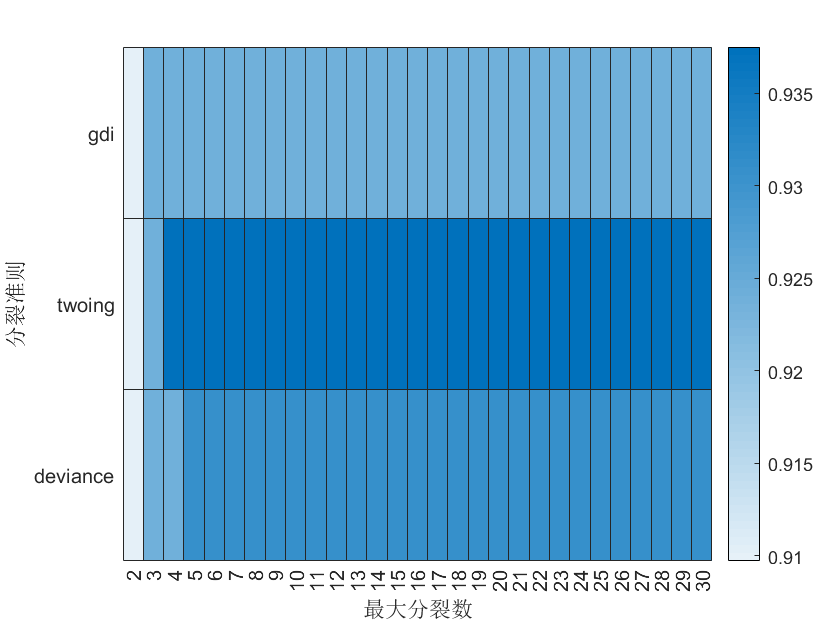

figure(6) % 第一列和其他相比太小了 去掉第一列重画
h_graph = heatmap(MaxNumSplits(2:end),SplitCriterion,MICRO_F1_SCORE(:,2:end));
h_graph.XLabel = '最大分裂数';
h_graph.YLabel = '分裂准则';

best_micro_f1_score = max(MICRO_F1_SCORE(:))

best_micro_f1_score = 0.9375

找到MICRO_F1_SCORE第一次出现最大值的位置

[r,c] = find(MICRO_F1_SCORE == best_micro_f1_score,1); 
best_SplitCriterion = SplitCriterion{r} % 分裂准则，元胞数组用大括号取出元素

best_SplitCriterion = 'twoing'

best_MaxNumSplits = MaxNumSplits(c)  % 决策树的最大分裂数

best_MaxNumSplits = 4

下面我们使用最优模型进行预测：

trainingData = data1;
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
predictors = inputTable(:, predictorNames);
response = inputTable.VarName5;
isCategoricalPredictor = [false, false, false, false];

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
classificationTree = fitctree(...
    predictors, ...
    response, ...
    'SplitCriterion', best_SplitCriterion, ...
    'MaxNumSplits', best_MaxNumSplits, ...
    'Surrogate', 'off', ...
    'ClassNames', categorical({'变色鸢尾'; '山鸢尾'; '维吉尼亚鸢尾'}));

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
treePredictFcn = @(x) predict(classificationTree, x);
trainedClassifier.predictFcn = @(x) treePredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
% trainedClassifier.RequiredVariables = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
% trainedClassifier.ClassificationTree = classificationTree;
% trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2017a.';
% trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');
% 
% % Extract predictors and response
% % This code processes the data into the right shape for training the
% % model.
% inputTable = trainingData;
% predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
% predictors = inputTable(:, predictorNames);
% response = inputTable.VarName5;
% isCategoricalPredictor = [false, false, false, false];
% 
% % Perform cross-validation
% partitionedModel = crossval(trainedClassifier.ClassificationTree, 'KFold', 5);
% 
% % Compute validation predictions
% [validationPredictions, validationScores] = kfoldPredict(partitionedModel);
% 
% % Compute validation accuracy
% validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');

trainedClassifier.predictFcn(data2)

ans = 6×1 categorical 数组
     山鸢尾 
     维吉尼亚鸢尾 
     山鸢尾 
     变色鸢尾 
     维吉尼亚鸢尾 
     山鸢尾 


`补充：三个参数的网格搜索`

trainingData = data1;
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
predictors = inputTable(:, predictorNames);
response = inputTable.VarName5;
isCategoricalPredictor = [false, false, false, false];


% 下面这两个变量在计算F1分数时会用到
ClassNames = unique(response); % y中各类的名称
group = response;  % y所在的那一列（真实的类别）


% Train a classifier
% This code specifies all the classifier options and trains the classifier.

SplitCriterion = {'gdi','twoing','deviance'}; %分裂准则有三个可以选的，这里用元胞数组保存
MaxNumSplits = 1:30;  % 最大分裂数（因为这个问题比较简单，我这里搜索设置的最大分裂数的上界是30）
MinLeafSize = 1:5; % 最小叶大小, 一个叶节点要存在所需要的最小样本量
num_i = length(SplitCriterion);  % 第一个超参数SplitCriterion的可能性有3种
num_j = length(MaxNumSplits);  % 第二个超参数MaxNumSplits的可能性有30种
num_q = length(MinLeafSize); % 第三个超参数MinLeafSize的可能性有5种
MICRO_F1_SCORE = zeros(num_i,num_j); % 初始化最后得到的结果（初始化是为了加快代码运行速度）
mywaitbar = waitbar(0);   % 设置一个进度条
TOTAL_NUM = num_i*num_j*num_q;  % 总共要计算多少次
now_num = 0; % 已经计算了多少次
for i = 1:num_i
    for j = 1:num_j
        for q = 1:num_q
            rng(520)  % 设定随机数种子，保证结果的可重复性(这里的520也可以换成其他的数字)
            %   注意，如果超参数是字符类型的话，它是被保存在元胞数组中的，取出时需要使用大括号才能得到字符型
            classificationTree = fitctree(...
                predictors, ...
                response, ...
                'SplitCriterion', SplitCriterion{i}, ...
                'MaxNumSplits', MaxNumSplits(j), ...
                'MinLeafSize' , MinLeafSize(q),  ...
                'Surrogate', 'off', ...
                'ClassNames', categorical({'变色鸢尾'; '山鸢尾'; '维吉尼亚鸢尾'}));
            
            %       'SplitCriterion' - Criterion for choosing a split. One of 'gdi'
            %                        (Gini's diversity index), 'twoing' for the twoing
            %                        rule, or 'deviance' for maximum deviance reduction
            %                        (also known as cross-entropy). Default: 'gdi'
            
            %       'MaxNumSplits' - Maximal number of decision splits (or branch
            %                        nodes) per tree. Default: size(X,1)-1
            
            % Create the result struct with predict function
            predictorExtractionFcn = @(t) t(:, predictorNames);
            treePredictFcn = @(x) predict(classificationTree, x);
            trainedClassifier.predictFcn = @(x) treePredictFcn(predictorExtractionFcn(x));
            
            % Add additional fields to the result struct
            trainedClassifier.RequiredVariables = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
            trainedClassifier.ClassificationTree = classificationTree;
            trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2017a.';
            trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');
            
            % Extract predictors and response
            % This code processes the data into the right shape for training the
            % model.
            inputTable = trainingData;
            predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
            predictors = inputTable(:, predictorNames);
            response = inputTable.VarName5;
            isCategoricalPredictor = [false, false, false, false];
            
            % Perform cross-validation
            partitionedModel = crossval(trainedClassifier.ClassificationTree, 'KFold', 5);
            
            % Compute validation predictions
            [validationPredictions, validationScores] = kfoldPredict(partitionedModel);
            
            % Compute validation accuracy
            validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
            
            % 下面就是计算每一次循环得到的micro F1分数
            C = confusionmat(group,validationPredictions,'Order',ClassNames);
            stats = statsOfMeasure(C);
            MICRO_F1_SCORE(i,j,q) = stats.microAVG(end);
            
            % 更新进度条
            now_num = now_num+1;
            mystr=['计算中...',num2str(100*now_num/TOTAL_NUM),'%'];
            waitbar(now_num/TOTAL_NUM,mywaitbar,mystr);
        end
    end
end

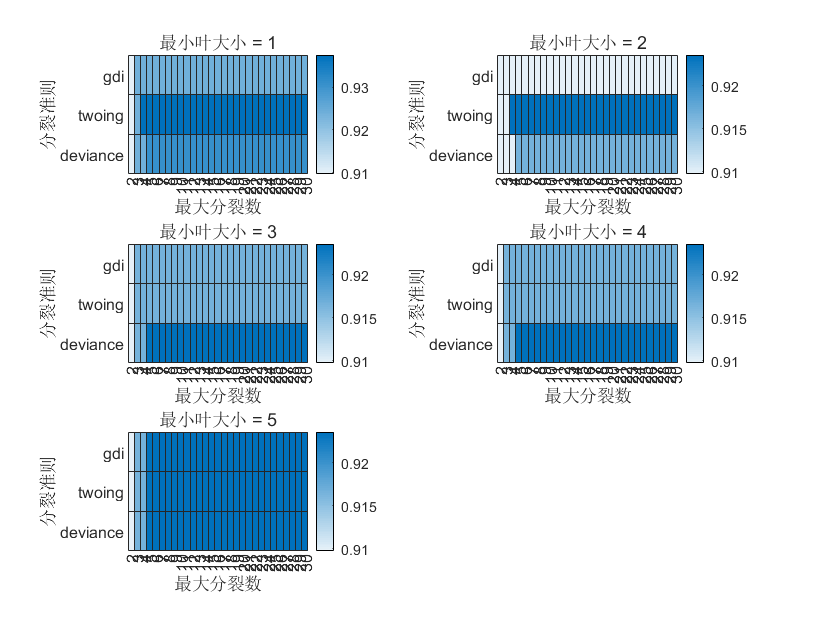

figure(7)  % 利用子图的方式来画热力图，但是这样的效果仍然不直观
for i = 1:num_q
    subplot(3,2,i)  % 绘制第i个子图
    h_graph =  heatmap(MaxNumSplits(2:end),SplitCriterion,MICRO_F1_SCORE(:,2:end,i));
    h_graph.XLabel = '最大分裂数';
    h_graph.YLabel = '分裂准则';
    title(['最小叶大小 = ', num2str(MinLeafSize(i))])
end

best_micro_f1_score = max(MICRO_F1_SCORE(:))

best_micro_f1_score = 0.9375

找到MICRO_F1_SCORE第一次出现最大值的位置

ind = find(MICRO_F1_SCORE == best_micro_f1_score,1);  % 线性索引
[a,b,c] = ind2sub(size(MICRO_F1_SCORE) ,ind);  % 线性索引转换为下标
best_SplitCriterion = SplitCriterion{a} % 分裂准则，元胞数组用大括号取出元素

best_SplitCriterion = 'twoing'

best_MaxNumSplits = MaxNumSplits(b)  % 决策树的最大分裂数

best_MaxNumSplits = 4

best_MinLeafSize = MinLeafSize(c)  % 决策树的最小叶大小

best_MinLeafSize = 1

`利用随机森林得到指标的重要性`

`（因为这个过程中具有随机性，所以每次运行的结果可能有细微区别，我们以某一次的结果为主就好了）`

trainingData = data1;
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
predictors = inputTable(:, predictorNames);
response = inputTable.VarName5;
isCategoricalPredictor = [false, false, false, false];

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
template = templateTree(...
    'MaxNumSplits', 143);
classificationEnsemble = fitcensemble(...
    predictors, ...
    response, ...
    'Method', 'Bag', ...
    'NumLearningCycles', 30, ...
    'Learners', template, ...
    'ClassNames', categorical({'变色鸢尾'; '山鸢尾'; '维吉尼亚鸢尾'}));


importance =oobPermutedPredictorImportance(classificationEnsemble);
 % 可以将重要性归一化到[0 1]区间内  % https://ww2.mathworks.cn/matlabcentral/answers/783611-need-predictor-importance-in-random-forest-expressed-as-a-percentage#answer_671247
importance(importance<0) = 0;
importance = importance./sum(importance)

importance =     0.0205         0    0.1905    0.7890


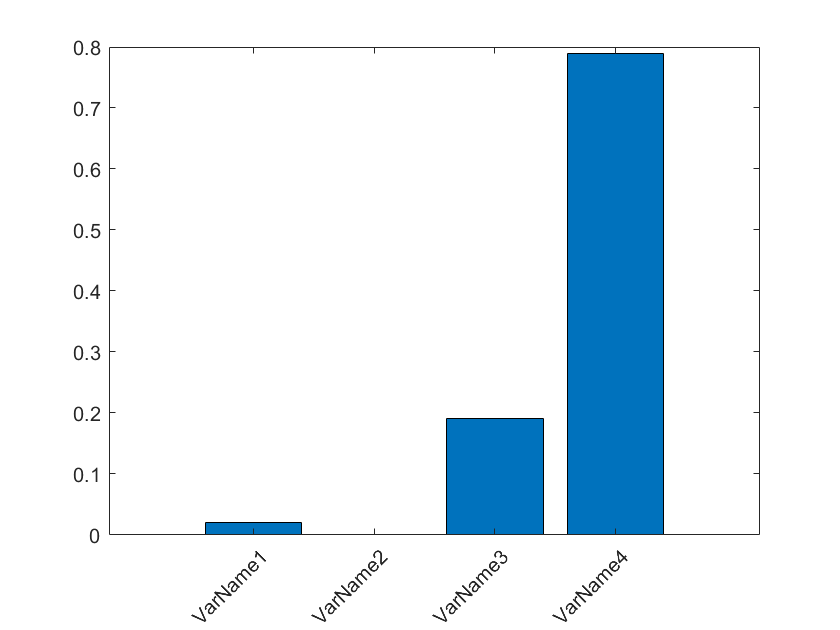

% 画一个柱状图
figure(8)
h_bar = bar(importance);
h_bar.Parent.XTickLabel =predictors.Properties.VariableNames;  % 设置每个柱子的标签
% 也可以手工指定这里的指标名称
% h_bar.Parent.XTickLabel = {'萼片长','萼片宽','花瓣长','花瓣宽'};
h_bar.Parent.XTickLabelRotation = 45;  % 标签旋转45度
h_bar.Parent.TickLabelInterpreter =  'none';  % 不使用latex语法

% 提取出大于某个阈值重要性的指标
threshold = 1/length(importance);  % 阈值默认为:1除以指标个数
ind = h_bar.Parent.XTickLabel(importance>threshold)

ind = 1×1 cell 数组
    {'VarName4'}


结果显示第三个指标和第四个指标的重要性最高

我们可以在分类学习器中只保留这两个指标重新进行训练，看看结果如何。

`下面我们利用随机森林得到样本属于某一类的概率`

注意：如果模型中具有随机性，那么最后得到的结果可能会变化。

我们可以使用rng指定一个固定的随机数种子，这样我们每次运行的结果都会相同。

rng(520)  % 设定随机数种子，保证结果的可重复性(这里的520也可以换成其他的数字)
trainingData = data1;
inputTable = trainingData;
predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
predictors = inputTable(:, predictorNames);
response = inputTable.VarName5;
isCategoricalPredictor = [false, false, false, false];

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
template = templateTree(...
    'MaxNumSplits', 143);
classificationEnsemble = fitcensemble(...
    predictors, ...
    response, ...
    'Method', 'Bag', ...
    'NumLearningCycles', 30, ...
    'Learners', template, ...
    'ClassNames', categorical({'变色鸢尾'; '山鸢尾'; '维吉尼亚鸢尾'}));

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
ensemblePredictFcn = @(x) predict(classificationEnsemble, x);
trainedClassifier.predictFcn = @(x) ensemblePredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifier.RequiredVariables = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
trainedClassifier.ClassificationEnsemble = classificationEnsemble;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2017a.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% % Extract predictors and response
% % This code processes the data into the right shape for training the
% % model.
% inputTable = trainingData;
% predictorNames = {'VarName1', 'VarName2', 'VarName3', 'VarName4'};
% predictors = inputTable(:, predictorNames);
% response = inputTable.VarName5;
% isCategoricalPredictor = [false, false, false, false];
% 
% % Perform cross-validation
% partitionedModel = crossval(trainedClassifier.ClassificationEnsemble, 'KFold', 5);
% 
% % Compute validation predictions
% [validationPredictions, validationScores] = kfoldPredict(partitionedModel);
% 
% % Compute validation accuracy
% validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');

[class_hat, score] = trainedClassifier.predictFcn(data2)

class_hat = 6×1 categorical 数组
     山鸢尾 
     维吉尼亚鸢尾 
     山鸢尾 
     变色鸢尾 
     维吉尼亚鸢尾 
     山鸢尾 


score =      0     1     0
     0     0     1
     0     1     0
     1     0     0
     0     0     1
     0     1     0
